# Prep fMRI data for connectivity or computational model-based anlayses

Below is a step‐by‐step tutorial for pre‐processing fMRI data for connectivity analyses and custom linear or computational reinforcement learning (RL) models using CANLAB tools. In this example, we create a denoised 4-D time series (an **fmri_data** object) for each participant, then use it for downstream analyses. The CANLAB toolboxes (see [CANLAB.github.io](https://canlab.github.io/)) offer functions for most of these steps. Feel free to adapt the code snippets to your specific dataset and analysis goals.

See also:

[https://canlab.github.io/_pages/tutorials/html/nuisance_covariates.html](https://canlab.github.io/_pages/tutorials/html/nuisance_covariates.html)

*canlab_connectivity_preproc()*

% Some formatting stuff for html
set(groot, 'DefaultFigurePosition', [200, 200, 900, 600], 'DefaultAxesFontSize', 12);

## A brief overview of steps

The code below loads some sample data and does the complete filtering and nuisance regression

% Load the key 4-D image file into an object

fname = which('swrsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz');
obj = fmri_data(fname);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 145720800 bytes
Loading image number:   150
Elapsed time is 0.713588 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
.fullpath should have image name for each image column in .dat
Attempting to expand image filenames in case image list is unexpanded 4-D images
Number of unique values in dataset: 493  Bit rate: 8.95 bits


______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | rmssd | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 18.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 2 3 4 5 6 

Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 22.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 2 3 4 5 6 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
Framewise Displacement (before and after >0.50 mm correction):
  0 images 
                               Outlier_c

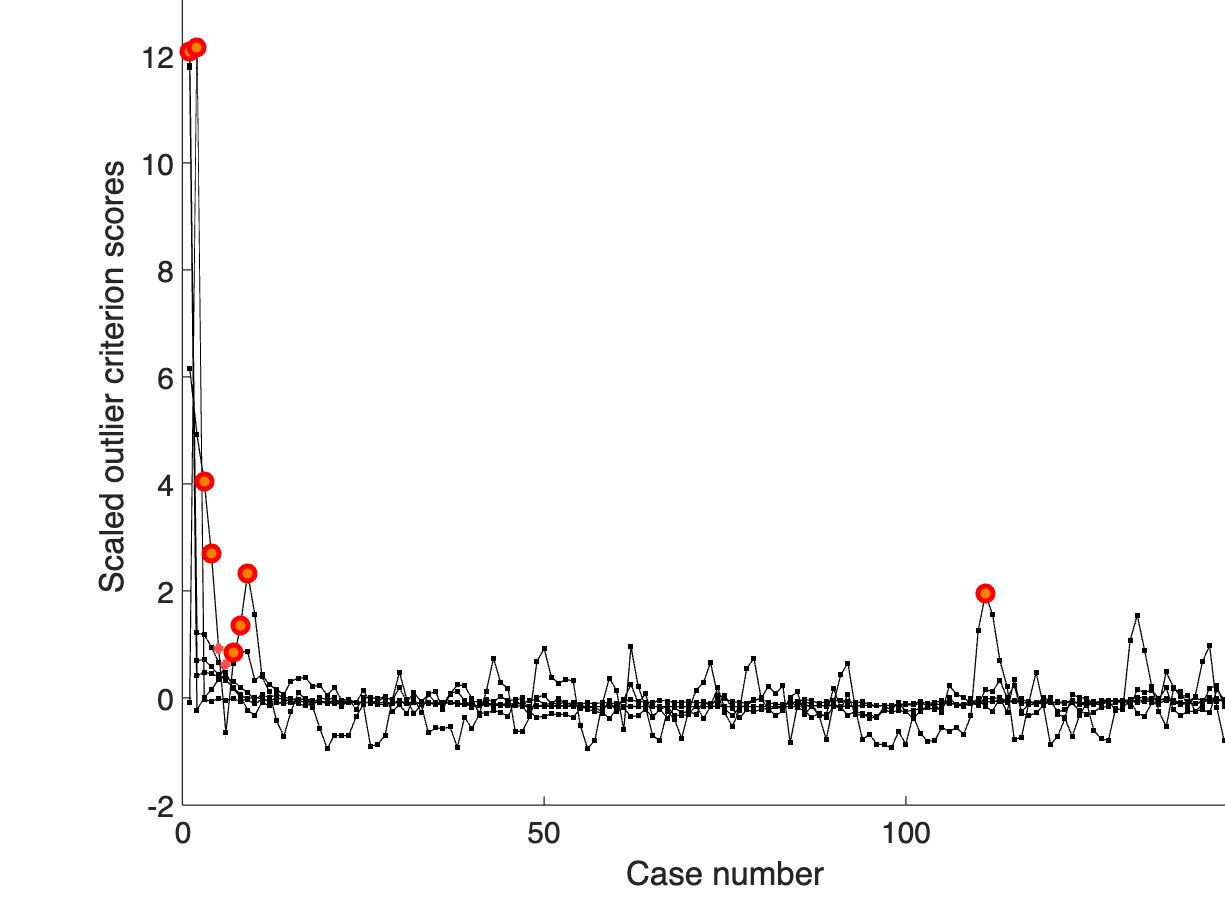


% Obtain a matrix of 'spike' indicators and movement-related regressors 
% based on multiple criteria to use as covariates

% 24 movement-related covariates per run
mvmtfname = which('rp_sub-sid001567_task-pinel_acq-s1p2_run-03_bold.txt');
[mvmt_matrix, mvmt_regs_24] = movement_regressors(mvmtfname);

covs = mvmt_regs_24;

% 'spike' outliers and high framewise-displacement (fd) images
[est_outliers_uncorr, est_outliers_corr, outlier_tables] = outliers(obj, 'fd', mvmt_matrix);

sum(est_outliers_uncorr) % this shows how many outliers

ans = 10


covs = [covs outlier_tables.outlier_regressor_matrix_uncorr];

% Mean CSF
[gwcsfvalues, gwcsfcomponents] = extract_gray_white_csf(obj);

Extracting from gray_matter_mask_sparse.img.
Removing 2565 voxels with one or more NaNs
Extracting from canonical_white_matter.img.
Removing 106 voxels with one or more NaNs
Extracting from canonical_ventricles.img.
Removing 158 voxels with one or more NaNs


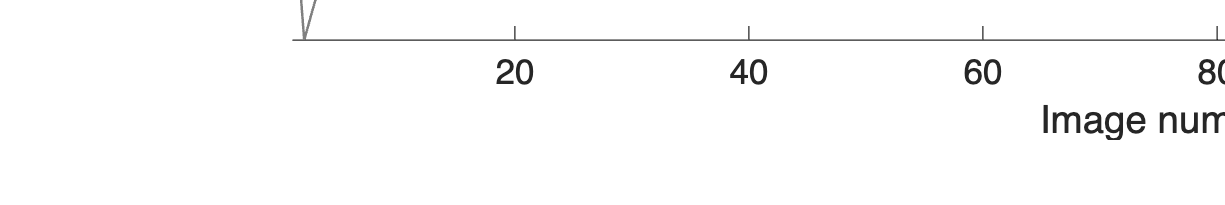

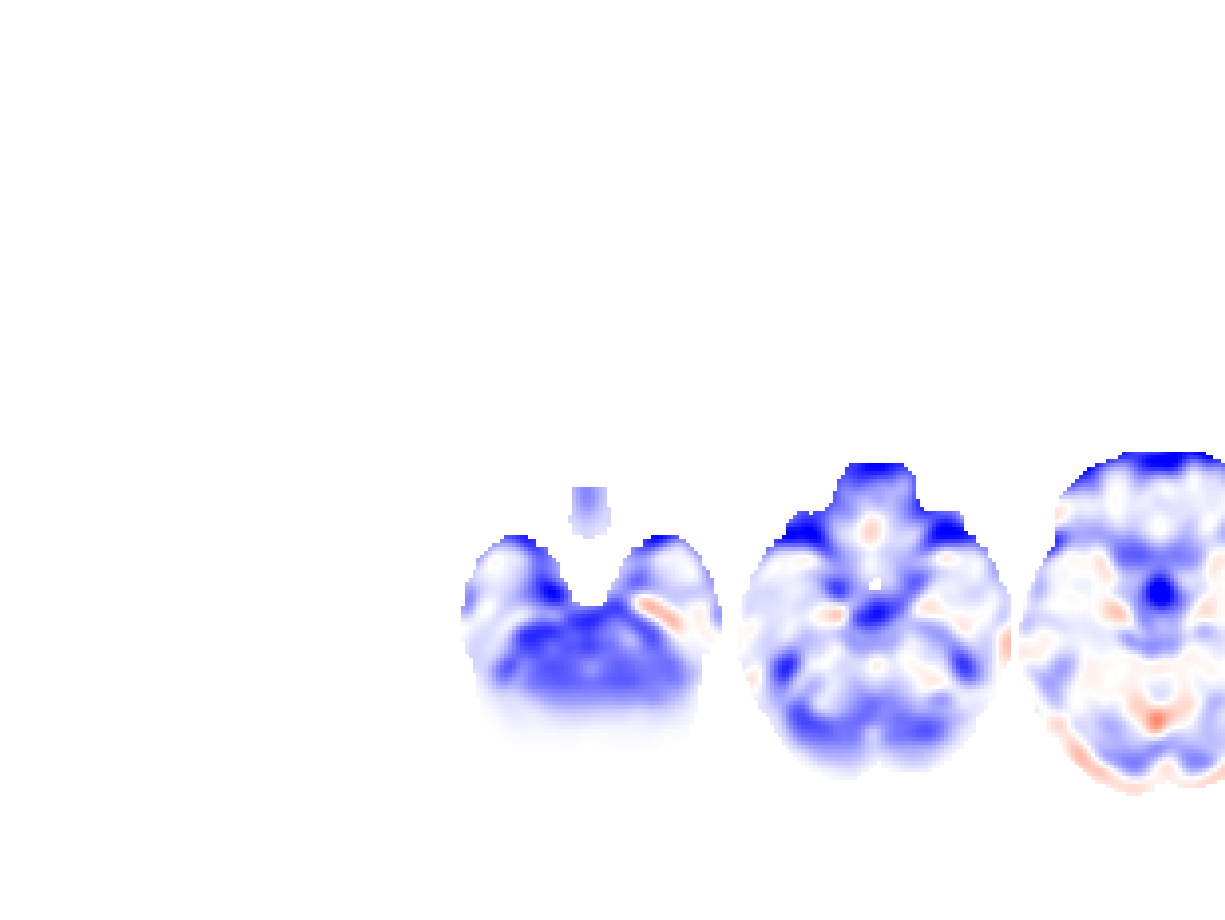

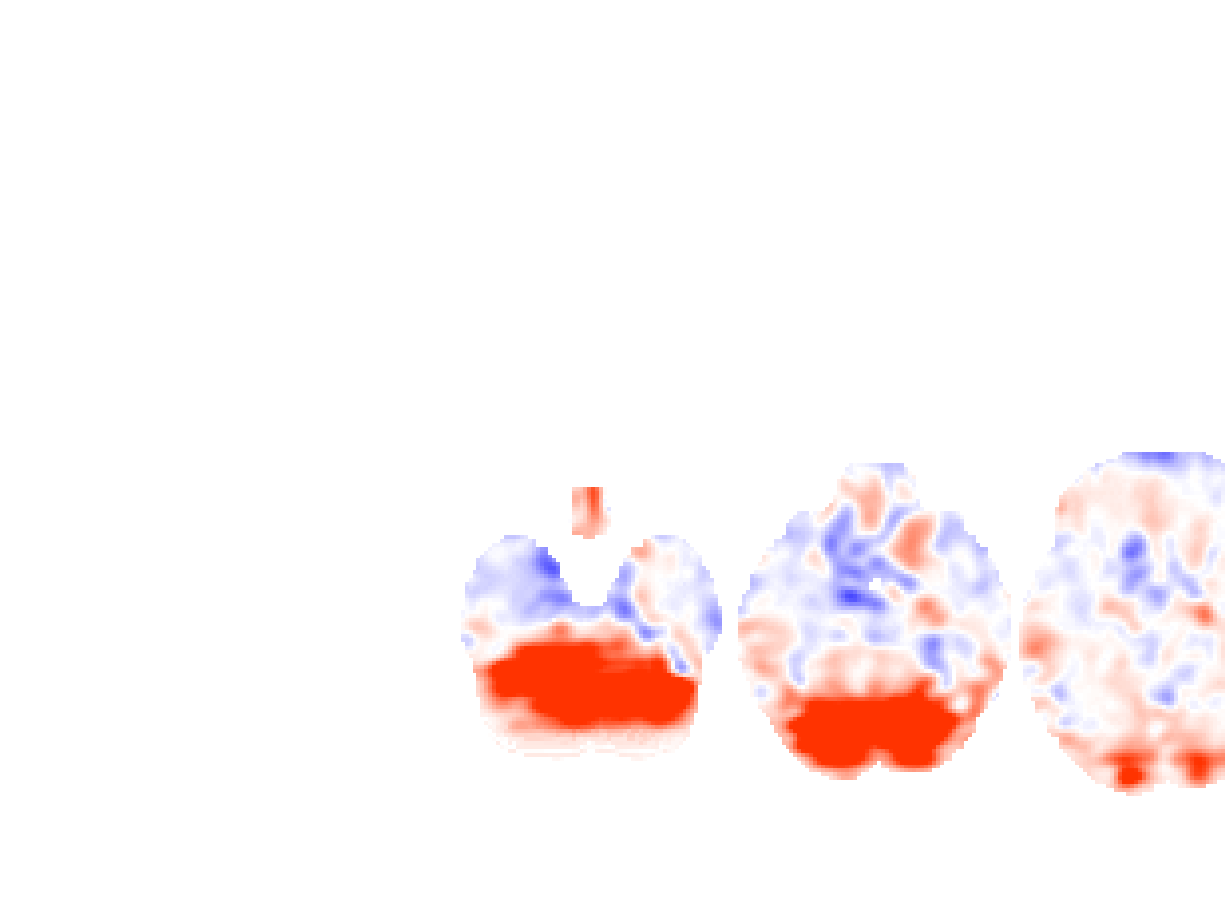

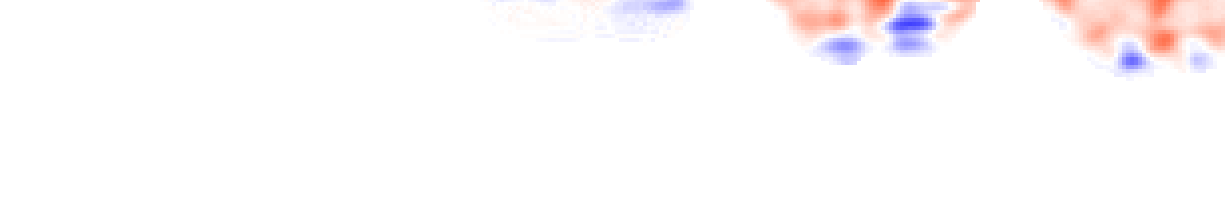

meancsf = gwcsfvalues(:, 3);
covs = [covs meancsf];

% Here the first component is a head-shift artifact; this will not always
% be the case. You could use PCA or ICA denoising strategies but be
% careful.  This code applies to this sample data only.
[component_scores, eigenmap_obj, explained] = pca(obj, 'k', 3);

covs = [covs component_scores(:, 1)];

% High-pass filter - assume TR = 2 sec
[S,KL,KH] = use_spm_filter(2, size(obj.dat, 2),'none', 'specify', 128);

covs = [covs KH];

% Regress all covs out from each voxel and return residuals
% We can ignore colinearity/leverage warnings

obj.X = covs;
regress_output = regress(obj, 'residual', 'noverbose');
obj_denoised = regress_output.resid;


## Step 1. Set Up Your Environment

- **Download and Install CANLAB Toolboxes:**

- Visit [CANLAB.github.io](https://canlab.github.io/) and download the latest version of the CANLAB tools.

- Add the CANLAB toolbox directories to your MATLAB (or compatible) path.

- Make sure you have other required dependencies (e.g., SPM if using its filtering routines).

- **Prepare Your Inputs:**

- **Time Series Data:** A 4-D NIfTI file per participant (e.g., from fmriprep).

- **Anatomical/Segmentation Outputs:** CSF, gray matter, and white matter masks (can be extracted using `extract_gray_white_csf_tissue_compartments.m`).

- **Motion and Outlier Information:** fmriprep output files or similar that contain motion parameters, displacement measures, and spike regressors.

## Step 2. Create the fmri_data Object

The `fmri_data` object in CANLAB is a container that holds your fMRI data along with metadata and processing options.

### Sample data

### Orientation to Pinel data files

The Pinel Localizer task was designed to probe several different types of basic cognitive processes, such as visual perception, finger tapping, language, and math. Several of the tasks are cued by reading text on the screen (i.e., visual modality) and also by hearing auditory instructions (i.e., auditory modality). The trials are randomized across conditions and have been optimized to maximize efficiency for a rapid event related design. There are 100 trials in total over a 5-minute scanning session. Read the original [paper](https://bmcneurosci.biomedcentral.com/articles/10.1186/1471-2202-8-91) for more specific details about the task and the [dataset paper](https://doi.org/10.1016/j.neuroimage.2015.09.052).

This dataset is well suited for these tutorials as it is (a) publicly available to anyone in the world, (b) relatively small (only about 5min), and (c) provides many options to create different types of contrasts. There are a total of 94 subjects available. 

Our **Pinel_data_sample_subject **is from an individual collected at Dartmouth's Brain Imaging Center (DBIC). It is organized in a particular standardized file format called BIDS (Brain imaging Data structure). The whole dataset is available in BIDS format from [Luke Chang's g-node GIN repository.](https://gin.g-node.org/ljchang/Localizer)

To have a look at this, let's go to the **Pinel_data_sample_subject **folder. Drag and drop it into your Command Window, or drag the folder into Terminal (Mac) and copy the path, then use the *cd( )* command in Matlab. e.g.,

 Now, let's look at the files:

ls  % list files

README.md			margulies
hcp_91k				transcriptomic_gradients
hcp_groupICAs



The main files we're interested in are:

`sub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii   `      

**The image data in 4-D Nifti format**

`sub-sid001567_task-pinel_acq-s1p2_run-03_events.tsv`        

**The task events + their onset times**

The rp_.txt file is only created after **realignment** of the functional images, a preprocessing step. We'll assume this is done already for now (which it was for this sample participant).  

After realignment with SPM software (or similar), some new files are created:

`rp_sub-sid001567_task-pinel_acq-s1p2_run-03_bold.txt `   

**The "realignment parameters" (rp), head motion estimates, with translation and rotation for each image required to match it to the *****reference image***** (often the first image in the series or an average image)**

`sub-sid001567_task-pinel_acq-s1p2_run-03_bold.mat`

**Matlab transformation matrices describing the voxel sizes, origin (zero-coordinate), and rotation for each image**

`rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii`

**The realigned image data, with the transformations (i.e., rotation/translation) applied**

`swrsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz`

**Smoothed (s), warped to MNI template (w), and realigned (r) 4-D image series. This is the one we are going to load and use for this example.**

To construct the design matrix for first-level analysis, we're mainly interested in two files: The [task (.tsv) file](http://task%20%28.tsv%29%20filehttps//bids-specification.readthedocs.io/en/stable/04-modality-specific-files/05-task-events.html) that tells us how to construct the regressors of interest, and the rp*.txt file that we'll use as a set of nuisance covariates. 

For further reading and information on file specifications, see the [docs on fmriprep preprocessing](https://fmriprep.org/en/stable/outputs.html), or [this](https://bookdown.org/u0243256/arc/brain-imaging-data-structure.html) or [this](https://sarenseeley.github.io/BIDS-fmriprep-MRIQC.html).

% Load the key 4-D image file 

fname = which('swrsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz');
obj = fmri_data(fname);

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 145720800 bytes
Loading image number:   150
Elapsed time is 0.625787 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
.fullpath should have image name for each image column in .dat
Attempting to expand image filenames in case image list is unexpanded 4-D images
Number of unique values in dataset: 493  Bit rate: 8.95 bits


## Step 3. Build the Nuisance Covariate Model

The goal is to create a design matrix that captures nuisance variance from multiple sources. This matrix typically includes:

**1. Intercepts:**Use `intercept_model.m` to generate indicator matrices for each run or session.

*This example dataset only includes one run, so we will omit it here, but it is important to include for multi-run data.*

**2. Motion Parameters: **Extract the 24 motion parameters per run (e.g., translations, rotations, and their derivatives/squares) from your fmriprep or SPM outputs.

% 24 movement-related covariates per run
mvmtfname = which('rp_sub-sid001567_task-pinel_acq-s1p2_run-03_bold.txt');
[mvmt_matrix, mvmt_regs_24] = movement_regressors(mvmtfname);

covs = mvmt_regs_24;


Let's plot them:

figure; plot(mvmt_matrix);
legend({'x' 'y' 'z' 'roll' 'pitch' 'yaw'});
title('Movement regressors')

**3. Mean CSF Signal: **Use either the fmriprep output or the CANLAB function:`FD = FD.extract_gray_white_csf();`

% Mean CSF
[gwcsfvalues, gwcsfcomponents] = extract_gray_white_csf(obj);

Extracting from gray_matter_mask_sparse.img.
Removing 2565 voxels with one or more NaNs
Extracting from canonical_white_matter.img.
Removing 106 voxels with one or more NaNs
Extracting from canonical_ventricles.img.
Removing 158 voxels with one or more NaNs


meancsf = gwcsfvalues(:, 3);
covs = [covs meancsf];

This extracts average signals from CSF (and optionally gray and white matter).

**4. Spike Regressors:**Identify and flag time points with unusual signal spikes (e.g., using FD.outliers).

**5. High Displacement Time Points:**Incorporate additional covariates for time points with high head displacement, as measured by geometric displacement metrics from fmriprep.

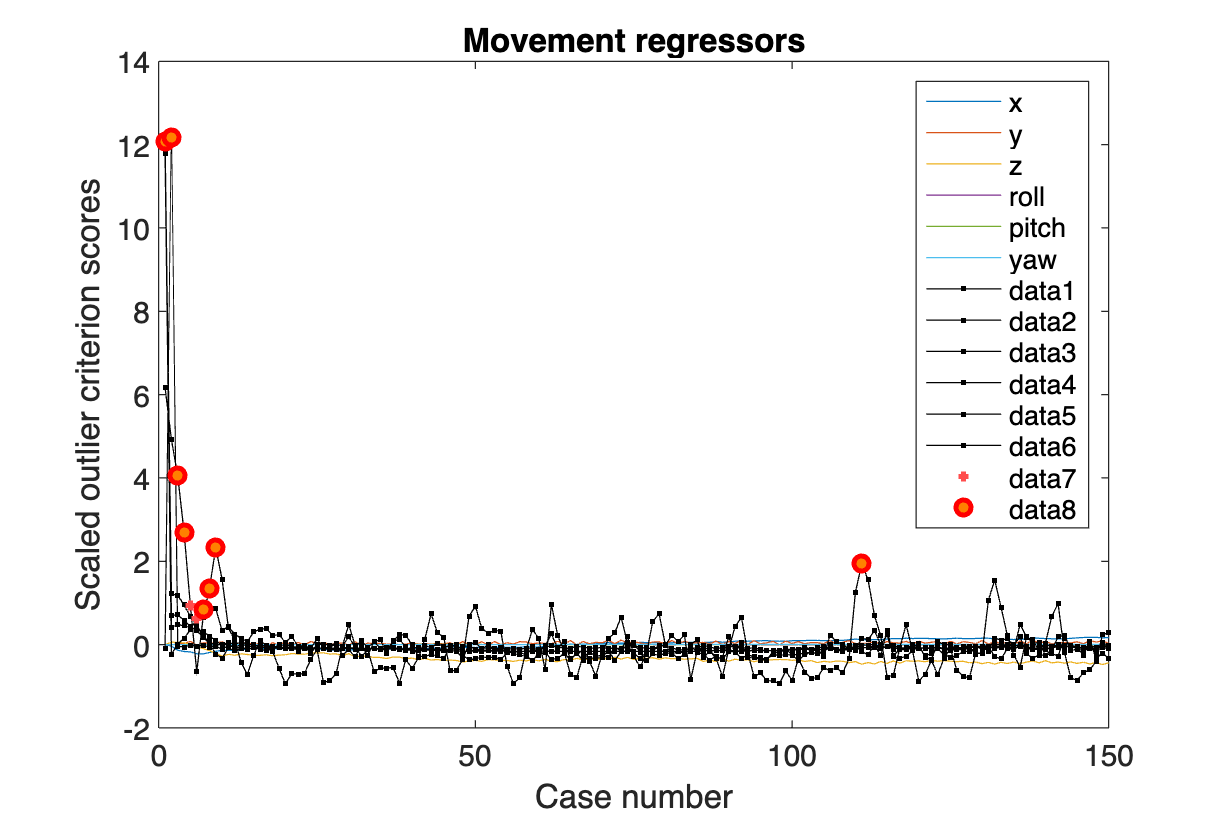

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | rmssd | Missing values |   0 images 


Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 18.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 2 3 4 5 6 

Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 22.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 2 3 4 5 6 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
Framewise Displacement (before and after >0.50 mm correction):
  0 images 
                               Outlier_c

% 'spike' outliers and high framewise-displacement (fd) images
[est_outliers_uncorr, est_outliers_corr, outlier_tables] = outliers(obj, 'fd', mvmt_matrix);

sum(est_outliers_uncorr) % this shows how many outliers

ans = 10


% each outlier or high-fd image gets its own regressor
covs = [covs outlier_tables.outlier_regressor_matrix_uncorr];


**6. High-Pass Filter (HPF) Regressors:**Generate HPF regressors to remove low-frequency drift. 

See also: [https://canlab.github.io/_pages/tutorials/html/high_pass_filtering.html](https://canlab.github.io/_pages/tutorials/html/high_pass_filtering.html)

For example, using SPM’s filtering functions:

`    cutoff = 128;  % Example cutoff in seconds; adjust as needed`

`    [HPreg, ~] = use_spm_filter(FD.dat, FD.TR, cutoff);`

*Note* that we need to know the TR for this! It's 2 sec. In BIDS formatted data, this can be found in the ".json sidecar" file, in the "RepetitionTime" field. We also need the scan length in sec, which in this case is 300 sec or 5 min.

% High-pass filter - assume TR = 2 sec
[S,KL,KH] = use_spm_filter(2, size(obj.dat, 2), 'none', 'specify', 128);

covs = [covs KH];

**covs: Combined nuisance regressors into nuisance design matrix X**

The various sets of regressors are concatenated into one matrix, covs.

This includes intercept, motion, CSF, spikes, high displacement (movement), HPF

## Step 4. Regress Out Nuisance Signals

Now, remove the nuisance variance from each voxel’s time series. The `fmri_data.regress` method with the `'residual'` option performs this operation:

`% Regress nuisance signals; output is the residual time series (denoised)`

`obj_denoised = obj.regress(nuisanceMat, 'residual');`

% Regress all covs out from each voxel and return residuals
% We can ignore colinearity/leverage warnings

obj.X = covs;
regress_output = regress(obj, 'residual', 'noverbose');
obj_denoised = regress_output.resid;

After this step, obj_denoised holds the denoised 4-D time series for further analysis.

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values | 

  0 images 




Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 52.00%
Expected 7.50 outside 95% ellipsoid, found  14

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 14 images		Cases 10 19 57 61 87 95 96 97 102 103 128 129 138 140 



Retained 12 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 53.33%
Expected 7.50 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 2 images		Cases 10 13 

Mahalanobis (cov and corr, q<0.05 corrected):
  0 images 
                               Outlier_count    Percentage
                               _____________    __________

    global_mean                      5            3.3333  
    global_mean_to_variance          1           0.66667  
    missing_values                   0                 0  
    rmssd_dvars                      0                 0  
    spatial_variability             11            7.3333  
    mahal_cov_uncor                 14            9.3333  
    

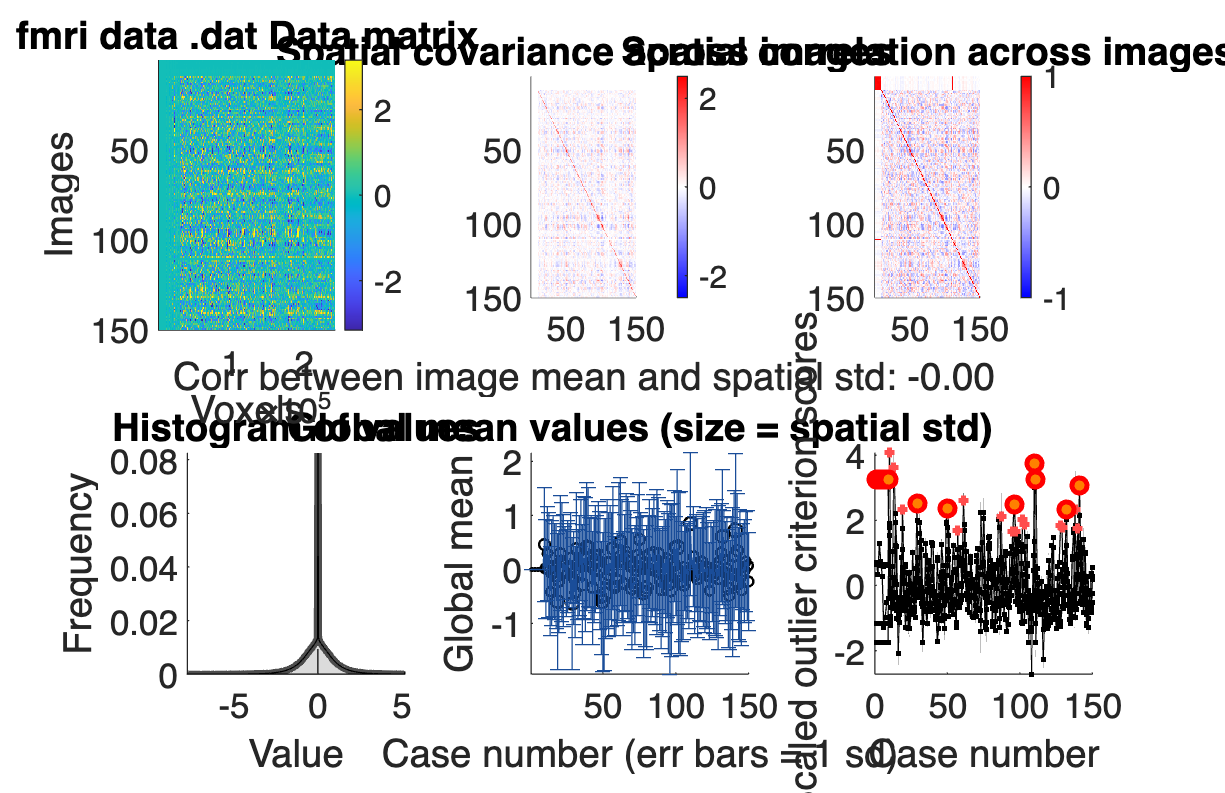

Grouping contiguous voxels:   1 regions
Grouping contiguous voxels:   1 regions
Grouping contiguous voxels:   1 regions


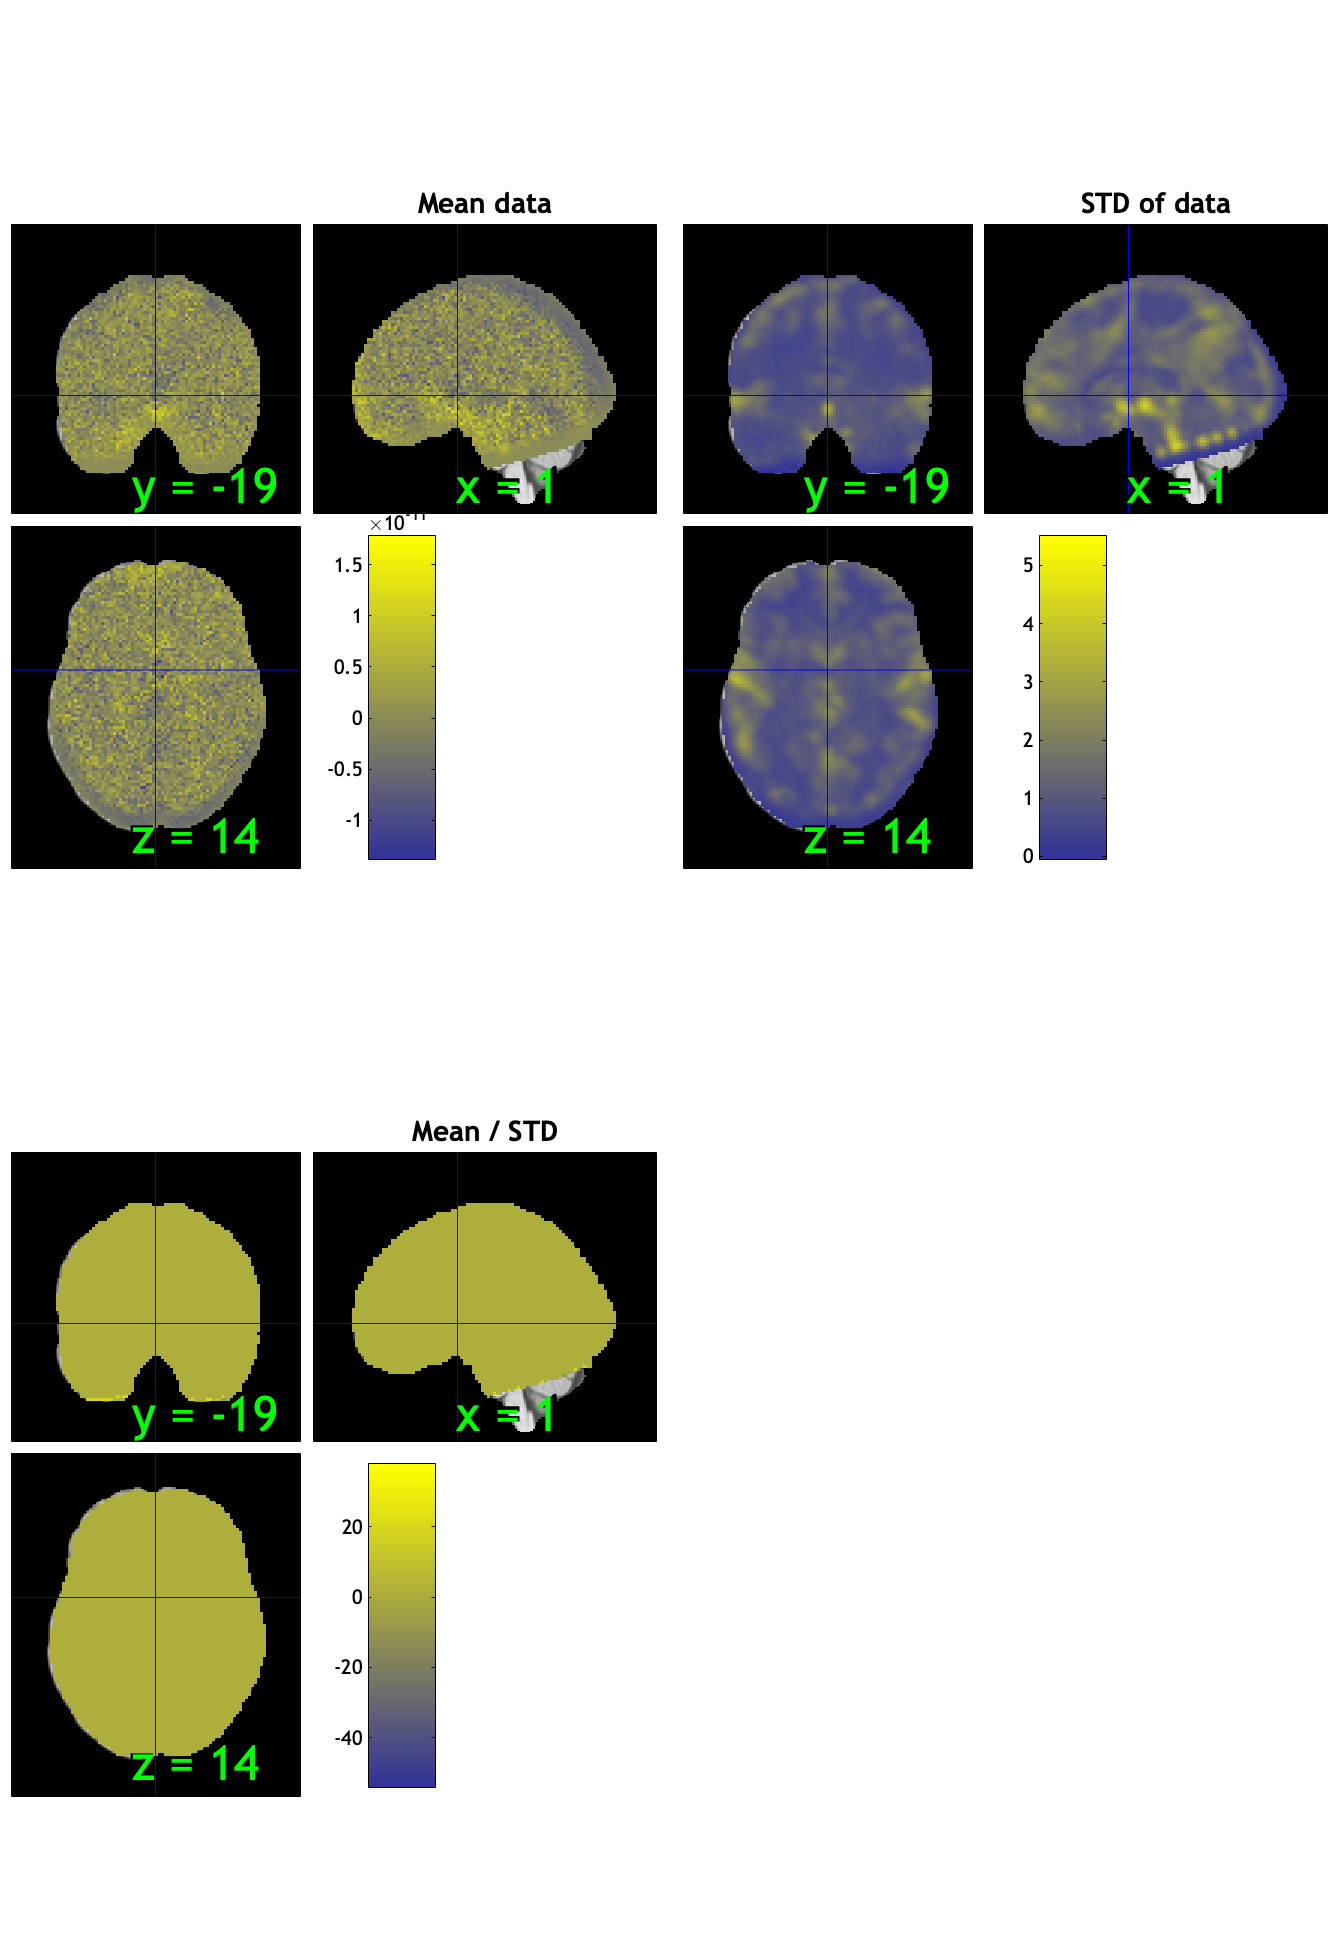

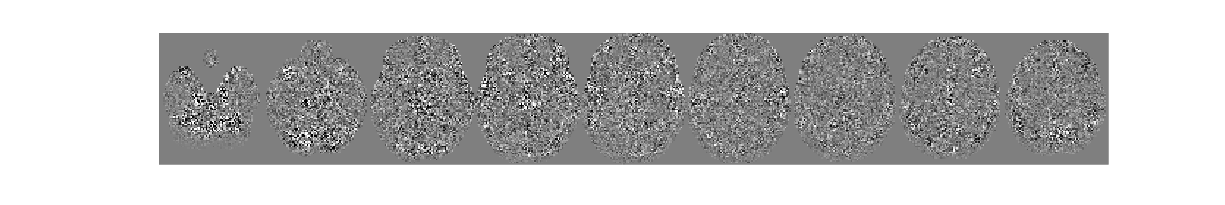

ans = 150×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


% Visualize the cleaned data

plot(obj_denoised)

## Step 5. Save the Preprocessed Data

Store the denoised fmri_data object and any relevant nuisance matrices for subsequent analyses:

This file can be loaded later for connectivity analyses or model fitting.

## Step 6. Optional: Explore how nuisance covs overlap with task design 

 Create a task design matrix from the Pinel task file

**Load the realignment parameters and create a set of nuisance covariates**

% Load the onsets file into a table object in matlab

taskdata = readtable('sub-sid001567_task-pinel_acq-s1p2_run-03_events.tsv', 'FileType', 'text');
taskdata

taskdata = 80×3 table
    onset    duration            trial_type         
    _____    ________    ___________________________

       0        1        {'video_computation'      }
     2.4        1        {'video_computation'      }
     8.7        1        {'horizontal_checkerboard'}
    11.4        1        {'audio_right_hand'       }
      15        1        {'audio_sentence'         }
      18        1        {'video_right_hand'       }
    20.7        1        {'audio_sentence'         }
    23.7        1        {'audio_left_hand'        }
    26.7        1        {'video_left_hand'        }
    29.7        1        {'audio_sentence'         }
      33        1        {'vertical_checkerboard'  }
    35.4        1        {'audio_computation'      }
      39        1        {'video_sentence'         }
    41.7        1        {'video_sentence'         }
    44.7        1        {'


% Use a CANlab function to extract the conditions (event types) and which
% events belong to each type
[indic, names] = string2indicator(taskdata.trial_type);
indic = logical(indic);

% Get a cell array of onsets for each condition
[ons, ons_with_durations] = deal(cell(1, length(names)));

for i = 1:length(names)
    ons{i} = taskdata.onset(indic(:, i));
    
    ons_with_durations{i} = taskdata.onset(indic(:, i));
    ons_with_durations{i}(:, 2) = taskdata.duration(indic(:, i));
end

Now, we've extracted the information in a format we can use to construct a design matrix. Let's try it. 

*Note* that we need to know the TR for this! It's 2 sec. In BIDS formatted data, this can be found in the ".json sidecar" file, in the "RepetitionTime" field. We also need the scan length in sec, which in this case is 300 sec or 5 min.

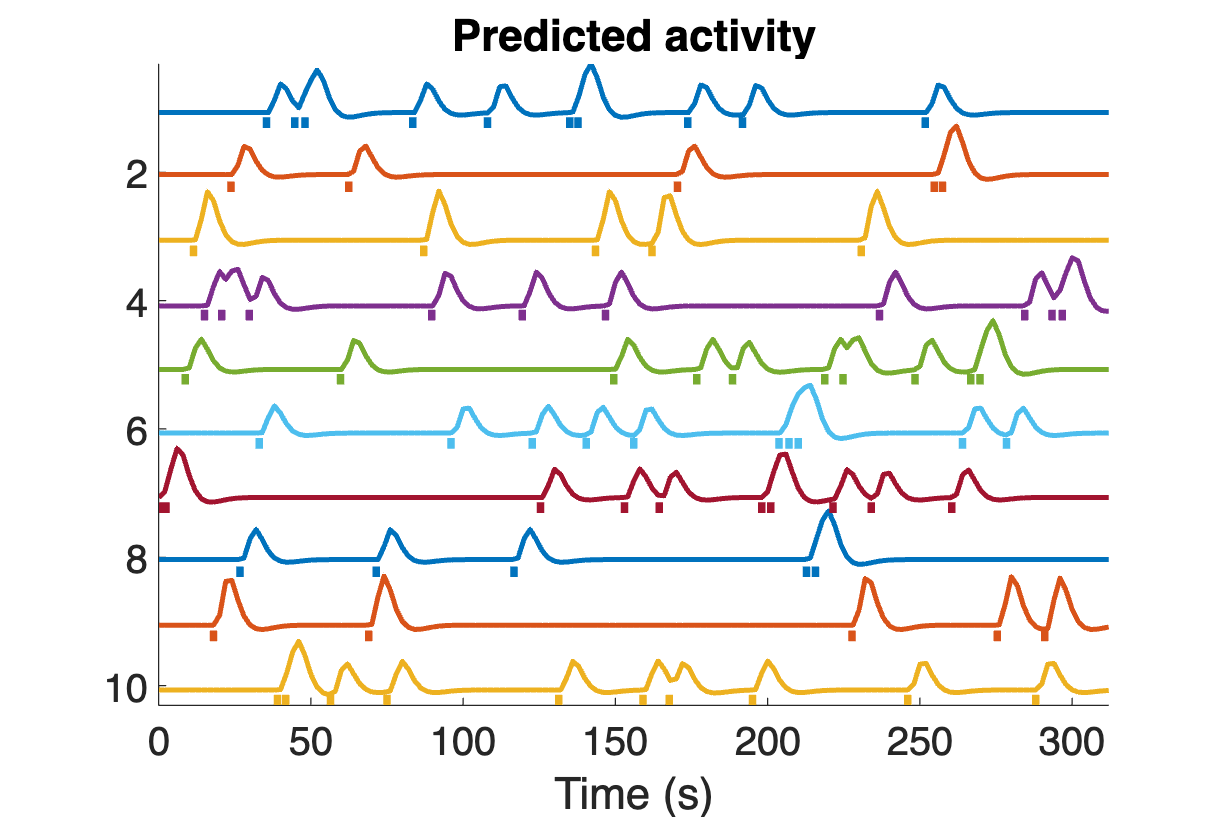

TR = 2;
X = onsets2fmridesign(ons, TR, 300);

% let's plot it
plotDesign(ons, [], TR);

This returns the task design matrix, X.

We can look at the Variance Inflation Factors to see whether there are mulitcolinearity issues or not. We'll use the 'plot' option and save the handle to this figure so we can re-activate it and add things later:

fig_han = create_figure('vifs'); % Get handle to current figure

vifs = getvif(X, 0, 'plot');

Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


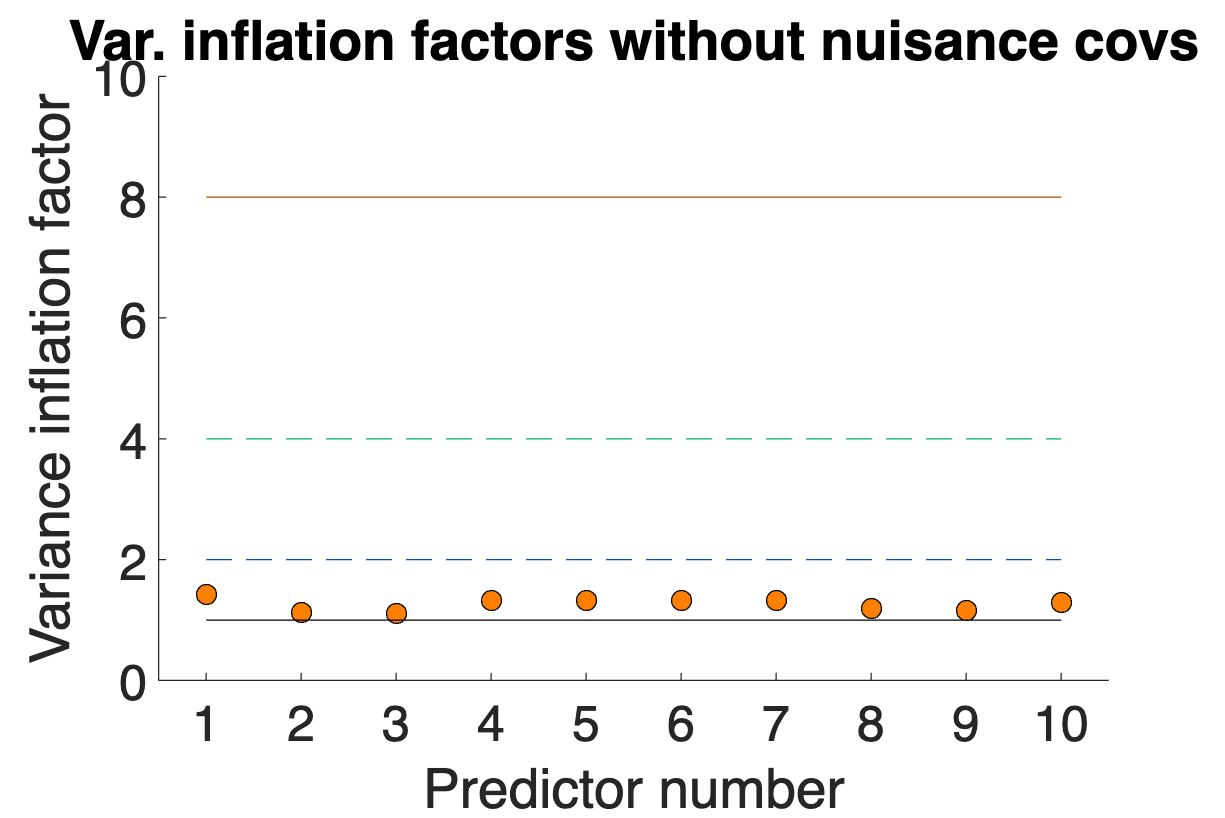

title('Var. inflation factors without nuisance covs')

Now let's see how VIFs are affected by nuisance covs:

fig_han = create_figure('vifs_with_covs'); % Get handle to current figure

vifs = getvif([X covs], 0, 'plot');

Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


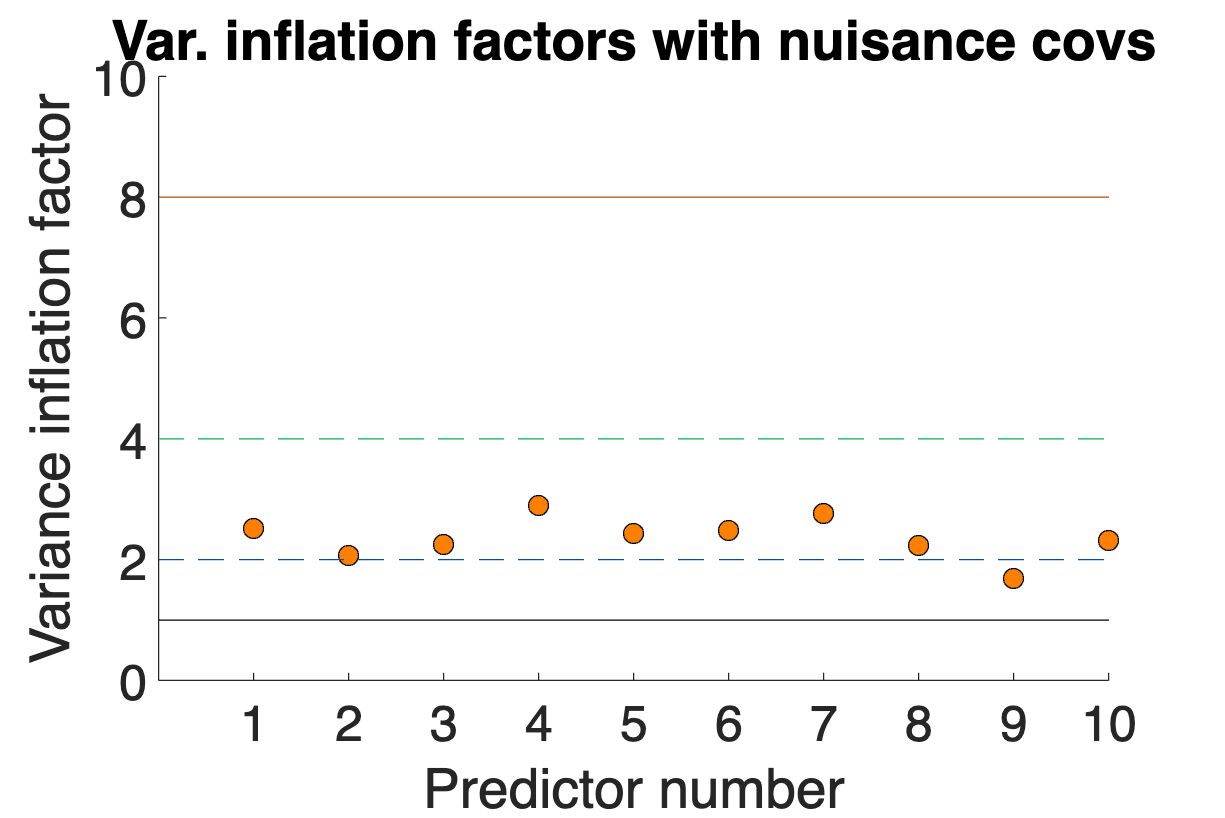


% We are interested in the task regs only, so zoom in on those:
set(gca, 'XLim', [0 10], 'YLim', [0 max(10, max(vifs(1:10)) + 0.5)]);
title('Var. inflation factors with nuisance covs')

## Step 6. Analysis: Connectivity and Custom RL Models

Once you have the cleaned data, you can proceed with various analyses:

**A. Connectivity Analysis**

**1. Extract Regional Time Series:**Use functions such as `extract_data` (or the CANLAB-supported `brainpathway` tools) to get time series from regions of interest (ROIs).`% Example: extract time series for a specific ROI`

**2. Compute Connectivity Metrics:**You can calculate correlation matrices, graph metrics, or other connectivity measures from the extracted time series.

See *canlab_connectivity_predict()*

**B. Custom Reinforcement Learning (RL) Models**

**1. Prepare the Data for Modeling:**Use the denoised voxel or ROI time series as inputs to your RL model.For instance, you might extract trial-by-trial signals aligned to task events.

**2. Fit Your RL Model:**Implement your RL model (e.g., using MATLAB’s optimization or Bayesian tools). You may code the model in MATLAB or interface with Python (e.g., via MATLAB’s Engine API).

**3. Evaluate Model Performance:**Analyze the model parameters, compare with behavioral data, or run statistical tests (e.g., using `fitlme`, `igls`, or CANLAB’s `fmri_data.regress` for second-level analysis).

## Summary

- **Data Loading:**Read the 4-D NIfTI into an `fmri_data` object.

- **Nuisance Modeling:**Build a nuisance regressor matrix using intercepts, motion, CSF, spike, high displacement, and HPF regressors.

- **Denoising:**Regress out the nuisance signals to create a cleaned dataset.

- **Saving:**Save the denoised data and nuisance matrices.

- **Analyses:**

- **Connectivity:** Extract ROI time series and compute connectivity measures.

- **RL Modeling:** Fit your custom reinforcement learning model to the cleaned time series.

By following these steps and using the CANLAB toolset, you can efficiently pre-process your fMRI data and set the stage for advanced connectivity and model-based analyses. Happy analyzing!